# Radar Array Optimization 

Written by team ArrAnt

University of Colorado Colorado Springs

Members:

-  Cynthia Valentine

-  Joseph Russ

-  Brianna McCague

-  Brett Ford

For and under the guidance of Northrop Grumman

## Input Parameters

Parameters inputed in the live script will be used in the radar_optimization script to create the population of pareto optimal solutions for radar arrays. The live script uses the optimization_output script to display a table and a graph of the solutions based on those paramaters.

 k= 0.6; % efficiency of attenae
 nu = 3;  % frequency (GHz) which is converted to meters for the loop gain
  
 num_styles = 4; % The number of distinct styles of radar array antennas that are permitted in the array  
 min_r_styles = 1; % the minimum number of styles that must to be recievers
 min_t_styles = 1; % the minimum number of styles that must to be transmitters

 min_diameter = 1;
 max_diameter = 40; % The maximum diamater (meters) of any given antenna in the array
    
 min_quantity =  1;
 max_quantity = 80; % The maximum quantity of antennas of one style in the array
      
 min_power = 100;
 max_power = 500000; % The maximum power (watts) for each antenna in the array
 
 max_antennas = 400; % The maximum total number of antennas in the array

 loop_gain_desired = 200; % The desired loop gain (dB) for the array
 
 year_built = 2030; % the year the array intends to be built

 include_monostatic = "T"; % change to a T to include monostatic antennas, change to a F to exclude monostatic antennas

## Radar Optimization

This calls the function to optimize the array based on the paramaters entered above.

tic
[x, operative_values] = radar_optimization(num_styles,min_t_styles,min_r_styles,min_quantity,max_quantity,min_diameter,max_diameter,min_power,max_power,year_built,include_monostatic,k,nu,max_antennas);

gamultiobj stopped because it exceeded options.MaxGenerations.


elapsed_time = toc;

num_rows = size(x, 1);
fprintf('Elapsed time: %.4f seconds\n', elapsed_time);

Elapsed time: 7.7188 seconds


%calculateParetoStrength(operative_values)
fprintf('Number of solutions: %d\n', num_rows);

Number of solutions: 53


## **Optimization Output**

    Table

- displays the optimal solutions of the optimization

- sorted by increasing gain and decreasing cost 

- includes the type, quantity and power of each style

obj_disp = optimization_output;
disp_table = obj_disp.create_table(x,num_styles, operative_values, include_monostatic,loop_gain_desired)

include_monostatic = "T"

disp_table = 53x18 table
    Gain (dB)    Cost ($M)        Type 1         Quantity 1    Diameter 1 (m)    Power 1 (W)        Type 2         Quantity 2    Diameter 2 (m)    Power 2 (W)        Type 3        Quantity 3    Diameter 3 (m)    Power 3 (W)        Type 4        Quantity 4    Diameter 4 (m)    Power 4 (W)
    _________    _________    _______________    __________    ______________    ___________    _______________    __________    ______________    ___________    ______________    _____

Graph

- displays the optimal solutions from the table 

- x axis: gain (dB), y axis: cost ($M)

- 2 green horizontal lines represent +- 10% of the desired loop gain

output_graph method called on the object:
  optimization_output with no properties.



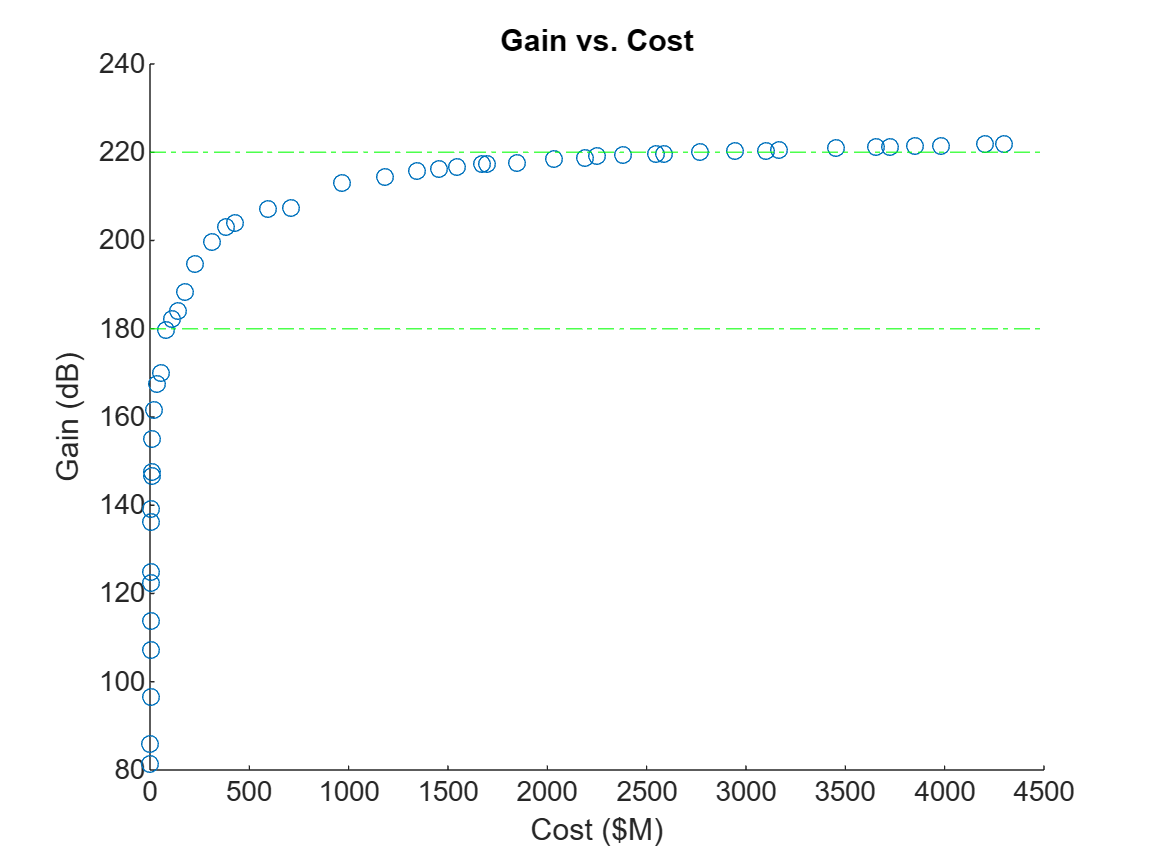

obj_disp.output_graph(loop_gain_desired, disp_table);

## **Save File as .xlsx**

list_parameters = [num_styles,min_t_styles,min_r_styles,min_quantity,max_quantity,min_diameter,max_diameter,min_power,max_power,year_built,include_monostatic,k,nu,max_antennas,loop_gain_desired];
obj_disp.saveFile(list_parameters,table);